## Define System Parameters

% Principal Moments of Inertia (kg-m^2)
Jxx = 0.02; Jyy = 0.002; Jzz = 0.002;

ts = 0.01;          % discrete time step

w_lin = [0 0 0];    % w values to linearize
q_lin = [0 0 0];    % q values to linearize

Q = eye(6);         % Q matrix for LQR
R = eye(3)*10;      % R matrix for LQR

## Nonlinear System Model

% Symbolic Terms for Nonlinear Model
syms q1 q2 q3 w1 w2 w3 u1 u2 u3

J = diag([Jxx Jyy Jzz]);
q = [q1; q2; q3];
w = [w1; w2; w3];
u = [u1; u2; u3];   % control input
x = [w; q];         % state

q0 = sqrt(1-q1^2-q2^2-q3^2);    % q0 (ensures q is a unit vector)

Omega = [q0 -q3 q2; q3 q0 -q1; -q2 q1 q0];

f = [J^-1*u; 0.5*Omega*w];      % Nonlinear EOM

% Compute A and B
for idx1 = 1:size(f,1)
    for idx2 = 1:size(x,1)
        A_nl(idx1,idx2) = diff(f(idx1),x(idx2));
    end
    for idx3 = 1:size(u,1)
        B_nl(idx1,idx3) = diff(f(idx1),u(idx3));
    end
end

## Linearized Model

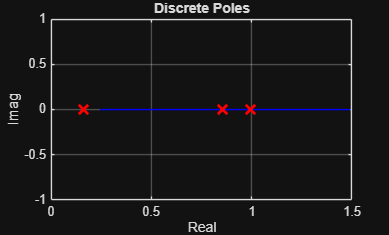

% Linearize A and B about q and w
A = double(subs(A_nl,[q1 q2 q3 w1 w2 w3],[q_lin, w_lin]));
B = double(subs(B_nl,[q1 q2 q3 w1 w2 w3],[q_lin w_lin]));
C = eye(6);

sys_o = ss(A,B,C,0);                    % continuous open-loop model

[K_d, S_d, P_d] = lqrd(A,B,Q,R,ts);     % discrete LQR
[K_c, S_c, P_c] = lqr(sys_o,Q,R);       % continuous LQR

A_cl_d = A-B*K_d;   % discrete closed-loop state matrix
A_cl_c = A-B*K_c;   % discrete closed-loop state matrix

sys_d = ss(A_cl_d,B,C,0);   % discrete closed-loop model
sys_c = ss(A_cl_c,B,C,0);   % continuous closed-loop model

% Discrete Pole Plot
figure;
plot([min(real(P_d)) max(real(P_d))]*1.5,[0 0],'b')
hold on
plot([0 0],[min(imag(P_d)),max(imag(P_d))]*1.5,'b')
plot(real(P_d),imag(P_d),'xr',LineWidth=2,MarkerSize=10)
grid on
title('Discrete Poles')
xlabel('Real')
ylabel('Imag')

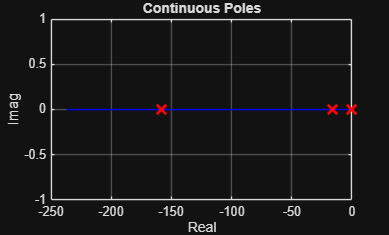


% Continuous Pole Plot
figure;
plot([min(real(P_c)) max(real(P_c))]*1.5,[0 0],'b')
hold on
plot([0 0],[min(imag(P_c)),max(imag(P_c))]*1.5,'b')
plot(real(P_c),imag(P_c),'xr',LineWidth=2,MarkerSize=10)
grid on
title('Continuous Poles')
xlabel('Real')
ylabel('Imag')

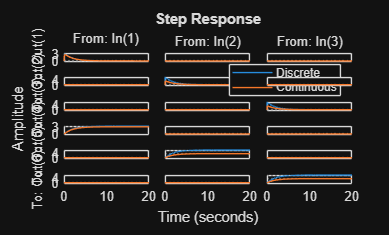


% Step Response
figure;
step(sys_d)
hold on
step(sys_c)
legend('Discrete','Continuous')

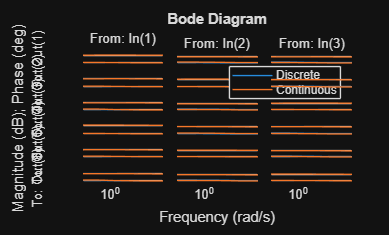


% Bode Plot
figure;
bode(sys_d)
hold on;
bode(sys_c)
legend('Discrete','Continuous')